% 没有加入冲量项的随机梯度下降法实现
syms x y real
y(x) = x^2+2*x+10 ;
delta(x) = -diff(y(x)) ;
step = 0.1 ;
first_x = 10 ;
x_current = first_x ;
x_next = first_x ;
show_tmp = 0 ;
show = [] ;
counter = 0 ;
delta_last = 0 ;
while (true)
    delta_x = double(delta(x_current))*step ;
    if(abs(delta_x) < 0.0001)
        break
    end
    x_next = x_current + delta_x ;
    x_current = x_next ;
    counter = counter + 1;
    show_tmp = x_next ;
    show = [show, show_tmp] ;
    if(counter > 200)
        break ;
    end
end
x_next

x_next = -0.9995

counter

counter = 45

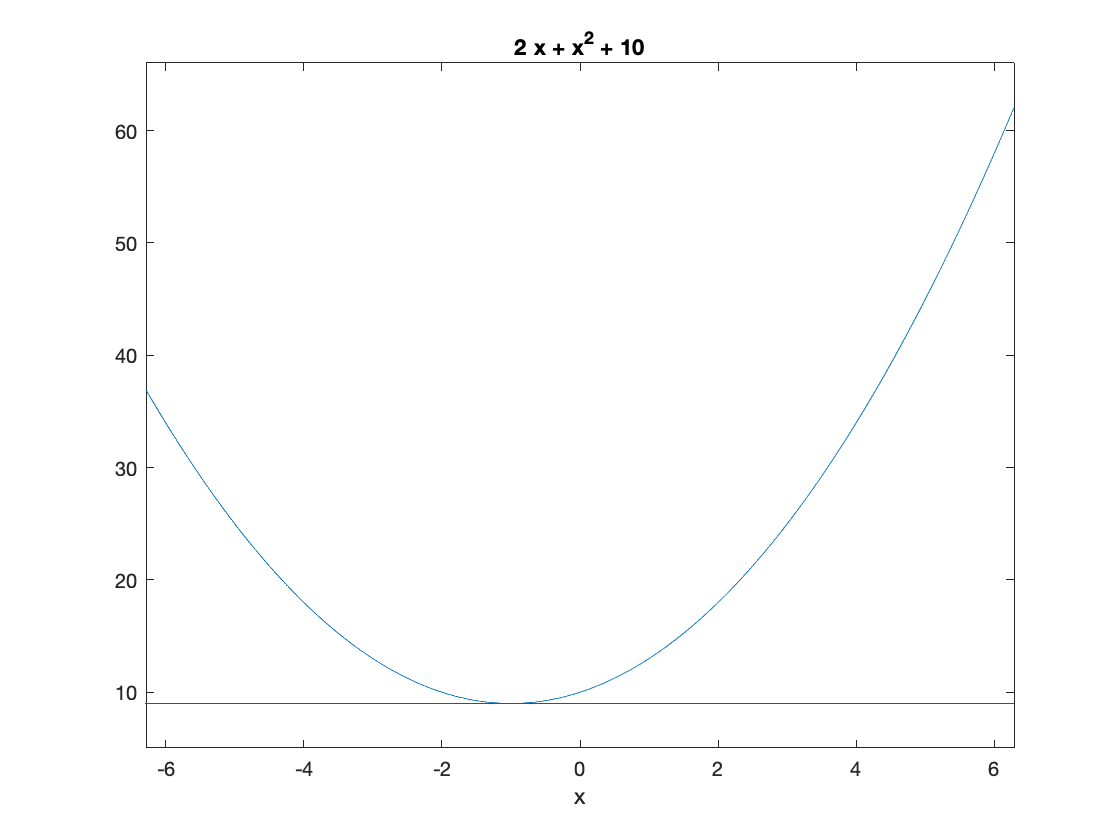

figure(1)
ezplot(y(x))
hold on 
plot([-100, 100],[double(y(x_next)), double(y(x_next))],'-r')

double(y(x_next))

ans = 9.0000

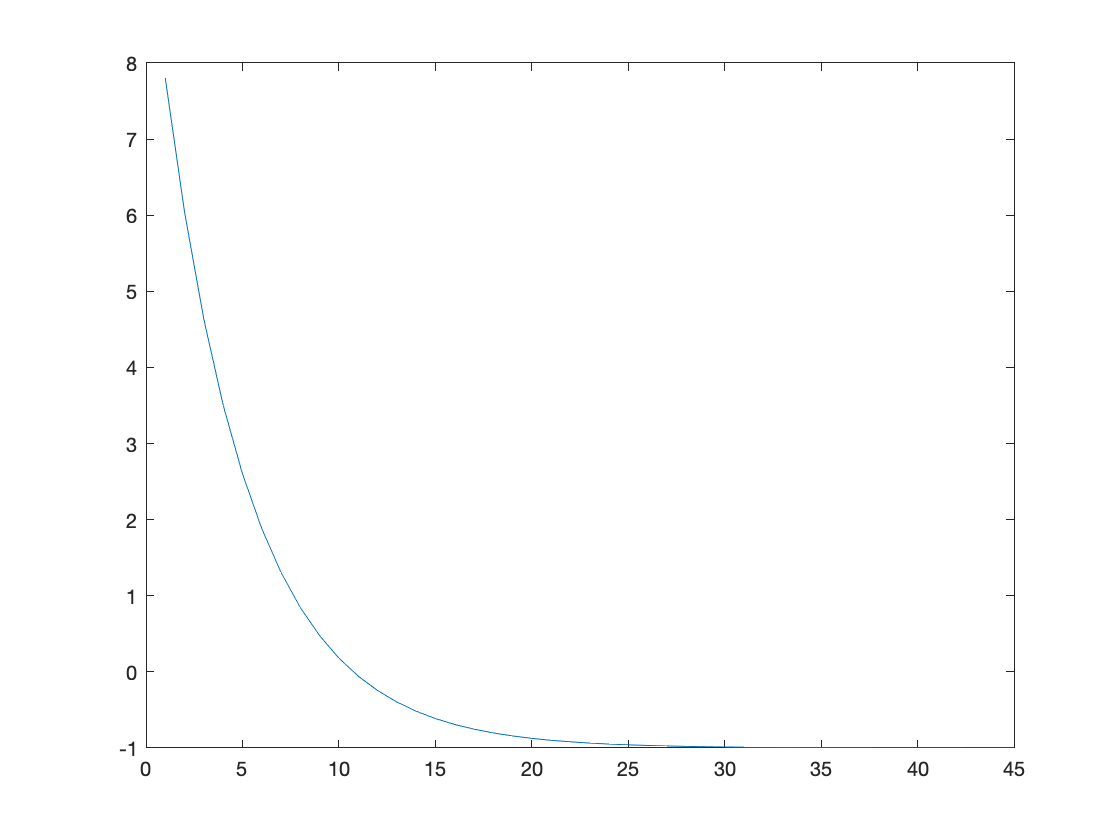

figure(2)
plot(show)